clc; clear;

%% 1. Constants & Material Properties
g = 9.81;                     % gravitational constant in m/s^2                    
m_system = 105/1000;          % mass of ride vehicle system in kg      
v_lift = 0.100;               % target lift hill velocity in m/s             
v_target_brake = 0.100;       % target braking section in m/s     
mu_roll = 0.0012;             % rolling friction coefficient
E_pla = 3.0e9;                % elastic modulus of PLA in Pa

% Auto brake strength
k_auto = 1.0;                 % damping coefficient for the electromagnetic braking

%% Track Cross Section
w_total = 0.04445;            % width of track from edge of one rail to the other in m
D = 6.35/1000;                % diameter of track rails in m
Rr = D/2;                     % radius of track rails in m
h = 0.002;                    % height of rectangular portion of track in m
b = w_total - 2*D;            % width of rectangular portion of track in m

%% Section Properties
A_rect = b*h;                 % area of rectangle in m^2
A_rail = pi*Rr^2;             % area of track rails in m^2

y_rect = h/2;                 % rectangle reaction in m
y_rail = h + Rr;              % rail reaction in m

y_NA = (A_rect*y_rect + 2*A_rail*y_rail)/(A_rect+2*A_rail); % Neutral axis location (area-weighted centroid of composite section)

I_rect = (b*h^3)/12 + A_rect*(y_rect-y_NA)^2; % Rectangle moment of inertia about NA (centroidal I + parallel axis shift)

I_rail = (pi*Rr^4)/4 + A_rail*(y_rail-y_NA)^2; % One rail (solid circle) moment of inertia about NA (centroidal I + parallel axis shift)

I = I_rect + 2*I_rail; % Total composite moment of inertia (rectangle + two rails)


%% Integration Settings
ds = 0.001; % Size step (m)        
v_max = 4.0; % Maximum velocity (m/s)         
R_min = 0.005; % Minimum radius of curvature (m)        

%% 2. Track Data
% Name, Straight Length, Radius, Z-Height, Shortened Name, Bank Angle
elements = {
    'Station Straight',      0.02350,  Inf,      0,         'Straight',         0;
    'Station Curve Down',    0.182,    0.18177,  -0.00075,  'Vertical Curve',   0;
    'Station - Straight',    0.19098,  Inf,      -0.01741,  'Straight',         0; 
    'Station Curve Up',      0.110,    0.11011,  -0.00045,  'Vertical Curve',   0;
    'Lifthill Entry Arc',    0.138,    0.100,    0.09692,   'Lift',             0; % New Addition: Lift Start
    'Vertical Lifthill',     0.24669,  Inf,      0.24669,   'Lift',             0;
    'Upper Crest Arc 1',     0.004,    0.050,    0.0040,    'Lift',             0; % New Addition: Lift Continued
    'Upper Crest Arc 2',     0.010,    0.050,    0.0100,    'Lift',             0; % New Addition: Lift End
    'Drop Curvature 1',      0.031,    0.05563,  -0.03125,  'Vertical Curve',   0;
    'Drop Curvature 2',      0.017,    0.03729,  -0.01702,  'Vertical Curve',   0;
    '1st Turn (Wide)',       0.1728,   0.110,    0,         'Horizontal Curve', 0;
    'Curve Down Straight'    0.040,    0.015,    -0.04,     'Vertical Curve',   0;
    'Straight After Drop',   0.26976,  Inf,      -0.0175,   'Straight',         0;
    'Curve Up',              0.015,    0.015,    0,         'Vertical Curve',   0;
    'Turn into Helix',       0.1021,   0.0650,   0,         'Horizontal Curve', 0;
    'Curve Down',            0.164,    0.16416,  -0.00011,  'Vertical Curve',   0;
    'Straight into Helix',   0.20778,  Inf,      -0.00715,  'Straight',         0;
    'Curve Down',            0.02581,  0.02581,  -0.0001,   'Curve',            0;
    'Helix (Main)',          1.429,    0.124,    -0.28803,  'Horizontal Curve', 0;
    'Curve Up Out of Helix', 0.019,    0.019,    -0.00131,  'Vertical Curve',   0;
    'Turn out of Helix',     0.248,    0.15801,  0,         'Horizontal Curve', 0;
    'Short Exit Straight',   0.02119,  Inf,      0,         'Straight',         0;
    '45 Degree Turn Part 1', 0.14481,  0.0922,   0,         'Horizontal Curve', 45;
    '45 Degree Turn Part 2', 0.135,    0.0859,   0,         'Horizontal Curve', -45;
    'Turn into Magnetic',    0.1257,   0.08,     0,         'Horizontal Curve', 0;
    'Brake Section',         0.47266,  Inf,      0,         'Brake',            0;
    'Turn into Station',     0.094,    0.06,     0,         'Horizontal Curve', 0;
};

%% 3. Simulation
t = 0;
v = v_lift;

t_log = []; v_log = []; Fn_log = []; Fl_log = [];
Gz_log = []; Gy_log = []; Gx_log = [];
FlexN_log = []; FlexL_log = []; FlexR_log = [];

fprintf('%-24s | %-7s | %-9s | %-9s | %-9s | %-9s | %-9s | %-6s\n',...
    'Section','Speed','Normal(N)','Lateral(N)','ResFlex(mm)','NormFlex(mm)','LatFlex(mm)','G');

Section                  | Speed   | Normal(N) | Lateral(N) | ResFlex(mm) | NormFlex(mm) | LatFlex(mm) | G     


fprintf('----------------------------------------------------------------------------------------------------------\n');

----------------------------------------------------------------------------------------------------------



for i = 1:size(elements,1)
    L_seg = elements{i,2};
    R = elements{i,3};
    dh_seg = elements{i,4};
    type = elements{i,5};
    bank = deg2rad(elements{i,6});

    if ~isinf(R)
        R = max(R,R_min);
    end

    N = max(1,round(L_seg/ds));
    ds_a = L_seg/N;
    dh_a = dh_seg/N;

    for j = 1:N

        %% --- Velocity Update ---
        if strcmpi(type,'Lift')
            % Smooth catch logic: slow down naturally until chain catches at v_lift
            v_natural = sqrt(max(0, v^2 - 2*g*dh_a - 2*mu_roll*g*ds_a));
            v = max(v_natural, v_lift);
        else
            % Gravity + rolling resistance
            v2 = v^2 - 2*g*dh_a - 2*mu_roll*g*ds_a;

            % --- Dynamic Brake ---
            if strcmpi(type,'Brake')
                remaining_dist = max(L_seg - j*ds_a, 0.001);
                a_req = (v_target_brake^2 - v^2)/(2*remaining_dist);
                if a_req > 0, a_req = 0; end
                k_mag = k_auto * abs(a_req)/max(v,0.1);
                a_brake = a_req - k_mag*v;
                v2 = v2 + 2*a_brake*ds_a;
            end

            v = sqrt(max(v2, 0));
        end

        v = min(v,v_max);

        % Prevent creeping in brake zone
        if strcmpi(type,'Brake') && v <= v_target_brake
            v = v_target_brake;
        end

        %% --- Force Calculations ---
        if isinf(R)
            Fn = m_system*g*cos(bank);
            Fl = -m_system*g*sin(bank);
        else
            ac = v^2/R;
            if contains(type,'Horizontal')
                Fn = m_system*(ac*sin(bank)+g*cos(bank));
                Fl = m_system*(ac*cos(bank)-g*sin(bank));
            elseif contains(type,'Vertical') || strcmpi(type,'Lift')
                if dh_a < 0
                    Fn = m_system*(g+ac);
                else
                    Fn = m_system*(g-ac);
                end
                Fl = 0;
            else
                Fn = m_system*g;
                Fl = 0;
            end
        end

        %% --- Deflection ---
        defl_n = (Fn*ds_a^3)/(48*E_pla*I);
        defl_l = (Fl*ds_a^3)/(48*E_pla*I);
        defl_r = sqrt(defl_n^2 + defl_l^2);

        %% --- G Forces ---
        Gz = Fn/(m_system*g);
        Gy = Fl/(m_system*g);
        Gx = 0; % Placeholder, calculated via diff later

        %% --- Time Update ---
        if v > 0
            t = t + ds_a/v;
        end

        %% --- Log ---
        t_log(end+1) = t;
        v_log(end+1) = v;
        Fn_log(end+1) = Fn;
        Fl_log(end+1) = Fl;
        FlexN_log(end+1) = defl_n*1000;
        FlexL_log(end+1) = defl_l*1000;
        FlexR_log(end+1) = defl_r*1000;
    end
    
    % Print Section Summary
    fprintf('%-24s | %-7.3f | %-9.2f | %-9.2f | %-9.3f | %-9.3f | %-9.3f | %-6.2f\n',...
        elements{i,1}, v, Fn, Fl, FlexR_log(end), FlexN_log(end), FlexL_log(end), Fn/(m_system*g));
end

Station Straight         | 0.097   | 1.03      | -0.00     | 0.000     | 0.000     | -0.000    | 1.00  
Station Curve Down       | 0.141   | 1.04      | 0.00      | 0.000     | 0.000     | 0.000     | 1.01  
Station - Straight       | 0.597   | 1.03      | -0.00     | 0.000     | 0.000     | -0.000    | 1.00  
Station Curve Up         | 0.603   | 1.38      | 0.00      | 0.000     | 0.000     | 0.000     | 1.34  
Lifthill Entry Arc       | 0.100   | 1.02      | 0.00      | 0.000     | 0.000     | 0.000     | 0.99  
Vertical Lifthill        | 0.100   | 1.03      | -0.00     | 0.000     | 0.000     | -0.000    | 1.00  
Upper Crest Arc 1        | 0.100   | 1.01      | 0.00      | 0.000     | 0.000     | 0.000     | 0.98  
Upper Crest Arc 2        | 0.100   | 1.01      | 0.00      | 0.000     | 0.000     | 0.000     | 0.98  
Drop Curvature 1         | 0.789   | 2.20      | 0.00      | 0.000     | 0.000     | 0.000     | 2.14  
Drop Curvature 2         | 0.978   | 3.72      | 0.00      | 0.0


%% Section Time Table
section_time = zeros(size(elements,1),1);
index_counter = 0;
for i = 1:size(elements,1)
    L_seg = elements{i,2};
    N = max(1,round(L_seg/ds));
    start_index = index_counter + 1;
    end_index   = index_counter + N;
    if start_index <= length(t_log) && end_index <= length(t_log)
        section_time(i) = t_log(end_index) - t_log(start_index);
    else
        section_time(i) = NaN;
    end
    index_counter = index_counter + N;
end

disp(' ');

disp('================ SECTION TIME TABLE ================');

================ SECTION TIME TABLE ================


disp(table(elements(:,1), section_time, 'VariableNames', {'Section_Name','Time_Seconds'}));

          Section_Name           Time_Seconds
    _________________________    ____________

    {'Station Straight'     }       0.22868  
    {'Station Curve Down'   }        1.5164  
    {'Station - Straight'   }       0.50777  
    {'Station Curve Up'     }       0.18163  
    {'Lifthill Entry Arc'   }        1.1992  
    {'Vertical Lifthill'    }        2.4569  
    {'Upper Crest Arc 1'    }          0.03  
    {'Upper Crest Arc 2'    }          0.09  
    {'Drop Curvature 1'     }      0.060298  
    {'Drop Curvature 2'     }      0.017876  
    {'1st Turn (Wide)'      }       0.17591  
    {'Curve Down Straight'  }       0.03374  
    {'Straight After Drop'  }       0.19489  
    {'Curve Up'             }     0.0097248  
    {'Turn into Helix'      }      0.070249  
    {'Curve Down'           }       0.11332  
    {'Straight into Helix'  }       0.14148  
    {'Curve Down'           }      0.016715  
    {'Helix

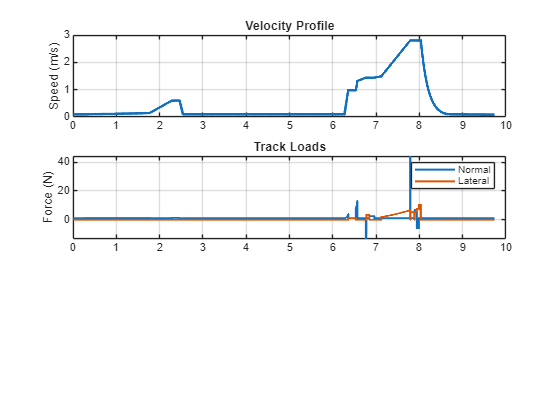

%% 4. Plots
figure('Color','w','Position',[100 100 900 650]);
subplot(3,1,1)
plot(t_log,v_log,'LineWidth',2)
grid on
ylabel('Speed (m/s)')
title('Velocity Profile')

subplot(3,1,2)
plot(t_log,Fn_log,'LineWidth',1.5)
hold on
plot(t_log,Fl_log,'LineWidth',1.5)
grid on
ylabel('Force (N)')
legend('Normal','Lateral')
title('Track Loads')

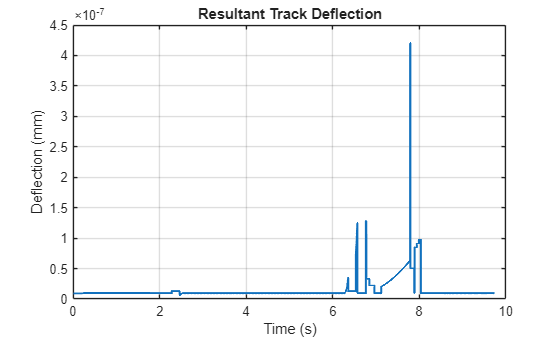


figure
plot(t_log, FlexR_log, 'LineWidth',1.5)
grid on
xlabel('Time (s)')
ylabel('Deflection (mm)')
title('Resultant Track Deflection')

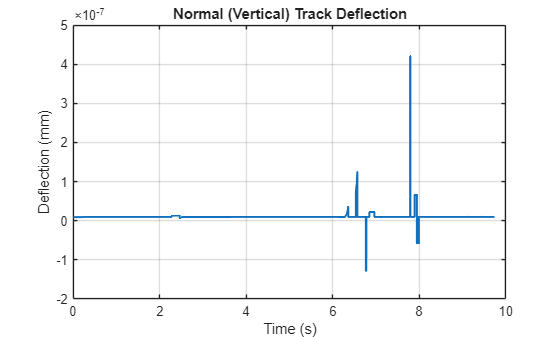


figure
plot(t_log, FlexN_log, 'LineWidth',1.5)
grid on
xlabel('Time (s)')
ylabel('Deflection (mm)')
title('Normal (Vertical) Track Deflection')

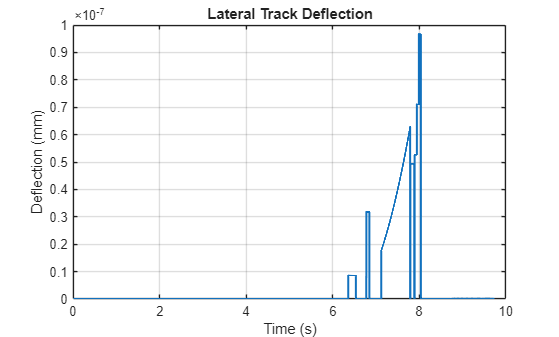


figure
plot(t_log, FlexL_log, 'LineWidth',1.5)
grid on
xlabel('Time (s)')
ylabel('Deflection (mm)')
title('Lateral Track Deflection')


%% 5. Maximum Value Summary
[maxFlexN, iN] = max(abs(FlexN_log));
[maxFlexL, iL] = max(abs(FlexL_log));
[maxFlexR, iR] = max(abs(FlexR_log));
[maxFn, iFn] = max(abs(Fn_log));
[maxFl, iFl] = max(abs(Fl_log));
[maxV, iV] = max(v_log);

G_log = sqrt((Fn_log./(m_system*g)).^2 + (Fl_log./(m_system*g)).^2);
[maxG, iG] = max(G_log);

fprintf('\n================ MAXIMUM VALUES SUMMARY ================\n');


================ MAXIMUM VALUES SUMMARY ================


fprintf('Max Normal Deflection    = %.3e mm\n', maxFlexN);

Max Normal Deflection    = 4.203e-07 mm


fprintf('Max Lateral Deflection   = %.3e mm\n', maxFlexL);

Max Lateral Deflection   = 9.666e-08 mm


fprintf('Max Resultant Deflection = %.3e mm\n', maxFlexR);

Max Resultant Deflection = 4.203e-07 mm


fprintf('Max Normal Force   = %.2f N\n', maxFn);

Max Normal Force   = 44.40 N


fprintf('Max Lateral Force  = %.2f N\n', maxFl);

Max Lateral Force  = 10.28 N


fprintf('Max Speed          = %.3f m/s\n', maxV);

Max Speed          = 2.801 m/s


fprintf('Max G-Force        = %.3f\n', maxG);

Max G-Force        = 43.104


fprintf('========================================================\n');

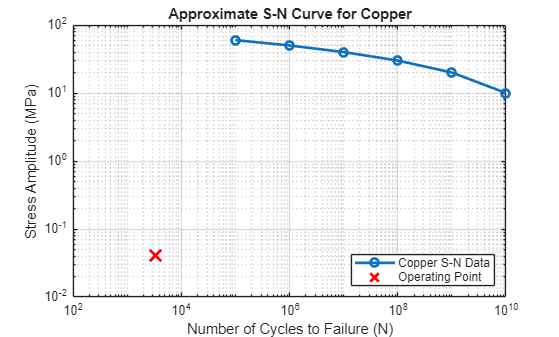


%% 6. Fatigue (S-N) Curve Plot for Copper
% Stress amplitude in MPa (typical handbook values)
S = [60 50 40 30 20 10];   % MPa
% Cycles to failure
N = [1e5 1e6 1e7 1e8 1e9 1e10];
% Worst-case stress amplitude (convert to MPa)
sigma_a = 41402/1e6;  % Pa -> MPa
figure('Color','w')
loglog(N,S,'o-','LineWidth',2)
hold on
% Plot your operating point
loglog(3.3e3, sigma_a,'rx','MarkerSize',12,'LineWidth',2)
grid on
xlabel('Number of Cycles to Failure (N)')
ylabel('Stress Amplitude (MPa)')
title('Approximate S-N Curve for Copper')
legend('Copper S-N Data','Operating Point','Location','SouthEast')


%% 7. Fatigue Damage (Miner's Rule)
%% ================================
%  Fatigue Damage (Miner's Rule)
%  Support Columns (Copper)
% ================================
%% ----- Stress Data (Pa) -----
% Long Tube (Worst Case)
sigma_max = 1.0892e5;   % Pa
sigma_avg = 4.4926e4;   % Pa
sigma_min = 2.6116e4;   % Pa
%% ----- Stress Amplitudes -----
sigma_a_high = (sigma_max - sigma_min)/2;
sigma_a_mid  = (sigma_avg - sigma_min)/2;
sigma_a_low  = (sigma_min)/2;
% Convert to MPa
Sa_high = sigma_a_high/1e6;
Sa_mid  = sigma_a_mid/1e6;
Sa_low  = sigma_a_low/1e6;
%% ----- Cycle Information -----
T_cycle = 10;          % seconds per lap
% Competition day
T_comp = 6*3600;         % 6 hours (s)
% Lifetime (3 years, 2 hr/week)
T_life = 2*52*3*3600;    % seconds
N_comp = 2*(T_comp/T_cycle);   % Two vehicles
N_life = 2*(T_life/T_cycle);
%% ----- Load Distribution -----
nH_comp = 0.15*N_comp;
nM_comp = 0.70*N_comp;
nL_comp = 0.15*N_comp;
nH_life = 0.15*N_life;
nM_life = 0.70*N_life;
nL_life = 0.15*N_life;
%% ----- Fatigue Life (Copper S-N Data) -----
Nf_high = 1e8;
Nf_mid  = 1e9;
Nf_low  = 1e10;
%% ================================
%  Competition Day Damage
% ================================
D_Hc = nH_comp/Nf_high;
D_Mc = nM_comp/Nf_mid;
D_Lc = nL_comp/Nf_low;
D_comp = D_Hc + D_Mc + D_Lc;
FoS_comp = 1/D_comp;
%% ================================
%  Lifetime Damage
% ================================
D_Hl = nH_life/Nf_high;
D_Ml = nM_life/Nf_mid;
D_Ll = nL_life/Nf_low;
D_life = D_Hl + D_Ml + D_Ll;
FoS_life = 1/D_life;
%% ================================
%  Display Results
fprintf('\n= FATIGUE ANALYSIS (SUPPORT COLUMNS) =\n');


= FATIGUE ANALYSIS (SUPPORT COLUMNS) =



fprintf('\n--- Competition Day ---\n');


--- Competition Day ---


fprintf('Total Cycles: %.0f\n',N_comp);

Total Cycles: 4320


fprintf('Damage:       %.3e\n',D_comp);

Damage:       9.569e-06


fprintf('FoS:          %.2e\n',FoS_comp);

FoS:          1.05e+05



fprintf('\n--- Full Lifetime ---\n');


--- Full Lifetime ---


fprintf('Total Cycles: %.0f\n',N_life);

Total Cycles: 224640


fprintf('Damage:       %.3e\n',D_life);

Damage:       4.976e-04


fprintf('FoS:          %.2e\n',FoS_life);

FoS:          2.01e+03


fprintf('\n=====================================\n\n');

%% ================================
%  Finite-Life Events (E-Stop / Maintenance)
% ================================
% Dynamic amplification factor
k_dyn = 3;     % Conservative
% E-stop stress amplitude (Pa)
sigma_E = k_dyn * sigma_a_high;
% Convert to MPa
Sa_E = sigma_E / 1e6;
% Number of special events (lifetime estimate)
N_Estop = 5*3;        % 5 per year, 3 years
N_maint = 10*3;       % 10 per year, 3 years
N_event = N_Estop + N_maint;
% Fatigue life at high stress
% Conservative estimate
Nf_E = 1e6;    % cycles to failure at high stress
% Damage from special events
D_event = N_event / Nf_E;
%  Total Lifetime Damage
% ================================
D_total_life = D_life + D_event;
FoS_total = 1 / D_total_life;
fprintf('\n--- Finite-Life Events ---\n');


--- Finite-Life Events ---


fprintf('Special Events: %d\n',N_event);

Special Events: 45


fprintf('Event Damage:   %.3e\n',D_event);

Event Damage:   4.500e-05


fprintf('\n--- Combined Lifetime ---\n');


--- Combined Lifetime ---


fprintf('Total Damage:   %.3e\n',D_total_life);

Total Damage:   5.426e-04


fprintf('Total FoS:      %.2e\n',FoS_total);

Total FoS:      1.84e+03



%% 8. Support Column Buckling
%% Material Properties (Copper)
E = 110e9;           % Young's Modulus (Pa)
%% Geometry (Converted to meters)
OD = 0.015875;       % Outer diameter (m)
ID = 0.01270;        % Inner diameter (m)
L_short = 0.041;     % Short tube length (m)
L_long  = 0.385;     % Long tube length (m)
%% End Condition Factor (Pinned-Pinned = Conservative)
K = 1.0;
%% Applied Load
P_applied = 2;       % Load per tube (N) (conservative)
%% Moment of Inertia (Hollow Circular Section)
I = (pi/64)*(OD^4 - ID^4);
%% Euler Buckling Loads
Pcr_short = (pi^2 * E * I)/(K*L_short)^2;
Pcr_long  = (pi^2 * E * I)/(K*L_long)^2;
%% Factors of Safety (Buckling)
FoS_short = Pcr_short / P_applied;
FoS_long  = Pcr_long  / P_applied;
%% Display Results
fprintf('---- Buckling Analysis Results ----\n');

---- Buckling Analysis Results ----


fprintf('Moment of Inertia: %.3e m^4\n\n', I);

Moment of Inertia: 1.841e-09 m^4



fprintf('Short Tube (L = %.3f m)\n', L_short);

Short Tube (L = 0.041 m)


fprintf('  Critical Load: %.2f N\n', Pcr_short);

  Critical Load: 1188764.70 N


fprintf('  Buckling FoS:  %.2f\n\n', FoS_short);

  Buckling FoS:  594382.35



fprintf('Long Tube (L = %.3f m)\n', L_long);

Long Tube (L = 0.385 m)


fprintf('  Critical Load: %.2f N\n', Pcr_long);

  Critical Load: 13481.62 N


fprintf('  Buckling FoS:  %.2f\n\n', FoS_long);

  Buckling FoS:  6740.81




%% 9. Tipping Analysis
% Dimensions in inches (base)
height_in = 1;
width_in  = 3.25;
length_in = 3.25;
% Convert to meters (base)
h_b = height_in * 0.0254;
w_b  = width_in  * 0.0254;
l_b = length_in * 0.0254;
g = 9.81;             % Gravity (m/s^2)
%% Material Properties
rho_copper = 8960;      % kg/m^3
rho_wood = 800;         % kg/m^3
%% Geometry (inches → meters)
OD_in = 0.625;          % Outer diameter (in)
ID_in = 0.5;            % Inner diameter (in)
OD = OD_in * 0.0254;    
ID = ID_in * 0.0254;
ro = OD/2;
ri = ID/2;
%% Lengths
L_column = 0.385;           % Column height (m)
L_track  = 0.001;           % Track height (m)
%% Volume Calculation (Hollow Cylinder)
V_column = pi*(ro^2 - ri^2)*L_column;
V_track  = pi*(ro^2 - ri^2)*L_track;
V_base = h_b * w_b * l_b;
%% Mass
m_column = rho_copper * V_column;
m_track  = rho_copper * V_track;
m_base = rho_wood * V_base;
%% Individual CG Locations (from ground)
h_column = L_column/2;
h_track  = L_column + L_track/2;
%% Combined CG
m_total = m_column + m_track + m_base;
h_total = (m_column*h_column + m_track*h_track) / m_total;
% Lateral Force
F_lat = 6.74/12;        % Lateral force (N)
% Weight
W = m_total * g;
% Moments
M_resist = W * (w_b/2);
M_tip    = F_lat * h_total;
% Factor of Safety
FoS_tipping = M_resist / M_tip;
% Display
fprintf('---- Support Column Tipping Results ----\n');

---- Support Column Tipping Results ----


fprintf('Total System Mass = %.3f kg\n', m_total);

Total System Mass = 0.385 kg


fprintf('Combined CG Height = %.3f m\n', h_total);

Combined CG Height = 0.124 m


fprintf('Resisting Moment  = %.3f Nm\n', M_resist);

Resisting Moment  = 0.156 Nm


fprintf('Tipping Moment    = %.3f Nm\n', M_tip);

Tipping Moment    = 0.069 Nm


fprintf('Tipping FoS       = %.3f\n', FoS_tipping);

Tipping FoS       = 2.246



%% 10. Guide Sprocket Analysis
g = 9.81;                 % gravity (m/s^2)
m_car = 0.105;          % mass of car + riders (kg)
mu = 0.02;            
F_chain_drive = m_car * g * (1 + mu);
guide_force_ratio = 0.15; 
F_guide = guide_force_ratio * F_chain_drive;
p = 12.7e-3;              
N = 14;                   
Dp = p / sin(pi/N);       
r_sprocket = Dp / 2;      
h_sprocket = 193e-3;      
rho_wood = 700;    % pine density (kg/m^3)
inch = 0.0254; % convert in to m
base_width  = 0.08255;    % tipping direction width (m)
base_length = 0.08255;    % length (m)
base_height = 0.0254;     % thickness (m)
V_base = base_width * base_length * base_height;
m_base = rho_wood * V_base;
W_base = m_base * g;
% Overturning moment
M_tip = F_guide * h_sprocket;
% Restoring moment (about edge)
d_restore = base_width / 2;   % tipping about side edge
M_restore = W_base * d_restore;
FoS_tipping = M_restore / M_tip;
% Shaft Bending Moment
M_bending = F_guide * r_sprocket;
fprintf('--- Guide Sprocket Analysis (Wood Base) ---\n');

--- Guide Sprocket Analysis (Wood Base) ---


fprintf('Guide sprocket force: %.3f N\n', F_guide);

Guide sprocket force: 0.158 N


fprintf('Overturning moment: %.4f N·m\n', M_tip);

Overturning moment: 0.0304 N·m


fprintf('Restoring moment: %.4f N·m\n', M_restore);

Restoring moment: 0.0491 N·m


fprintf('Factor of Safety (tipping): %.2f\n', FoS_tipping);

Factor of Safety (tipping): 1.61


fprintf('Sprocket shaft bending moment: %.4f N·m\n', M_bending);

Sprocket shaft bending moment: 0.0045 N·m



if FoS_tipping >= 1.5
    fprintf('RESULT: System is stable with acceptable margin.\n');
else
    fprintf('RESULT: System is NOT stable under worst-case assumptions.\n');
end

RESULT: System is stable with acceptable margin.


%% 11. ASTM G-Analysis
dt_log = [diff(t_log), mean(diff(t_log))];
Gx_log = [0, diff(v_log)] ./ (max(dt_log, 1e-6) * g);
Gy_log = Fl_log ./ (m_system * g);
Gz_log = Fn_log ./ (m_system * g);
fprintf('\n================ ASTM RIDER G ANALYSIS ==================\n');


================ ASTM RIDER G ANALYSIS ==================


fprintf('Max +Gx (Forward)  = %.3f\n', max(Gx_log));

Max +Gx (Forward)  = 1.644


fprintf('Max +Gy (Lateral)  = %.3f\n', max(abs(Gy_log)));

Max +Gy (Lateral)  = 9.983


fprintf('Max +Gz (Vertical) = %.3f\n', max(Gz_log));

Max +Gz (Vertical) = 43.104


fprintf('=========================================================\n');


% Sprocket Torque Calculations

m = 0.105;              % kg (ride vehicle mass)
g = 9.81;               % m/s^2
a = 0;                  % acceleration (0 = constant speed)
eta = 0.85;             % drivetrain efficiency
servo_torque_kgcm = 1.3;  % kg*cm (peak torque)
servo_rpm = 130;          % RPM
servo_torque = servo_torque_kgcm * 0.09807;   % Convert to N*m
omega = (2*pi*servo_rpm)/60;                  % rad/s

% SPROCKET (14T, 1/2" pitch)
T = 14;              % teeth
p = 0.0127;          % meters (1/2 inch chain pitch)
Dp = p / sin(pi/T);  % pitch diameter
r = Dp/2;            % pitch radius
% FORCE REQUIRED
F_required = m*(g + a);
% TORQUE REQUIRED AT SPROCKET
T_required = F_required * r;
% Account for efficiency
T_actual = T_required / eta;
% LIFT SPEED
v = omega * r;     % m/s
% POWER ANALYSIS
P_required = F_required * v;   % Watts required
P_motor = servo_torque * omega; % Motor power
% FACTOR OF SAFETY
FoS = servo_torque / T_actual;
% OUTPUT RESULTS
fprintf('\n===== LIFT REQUIREMENTS =====\n');


===== LIFT REQUIREMENTS =====


fprintf('Required Force: %.3f N\n', F_required);

Required Force: 1.030 N


fprintf('Required Torque at Sprocket: %.4f N*m\n', T_required);

Required Torque at Sprocket: 0.0294 N*m


fprintf('Torque w/ Efficiency Loss: %.4f N*m\n', T_actual);

Torque w/ Efficiency Loss: 0.0346 N*m



fprintf('\n===== MOTOR =====\n');


===== MOTOR =====


fprintf('Servo Torque (N*m): %.4f\n', servo_torque);

Servo Torque (N*m): 0.1275


fprintf('Motor Power (W): %.3f\n', P_motor);

Motor Power (W): 1.736



fprintf('\n===== POWER REQUIRED =====\n');


===== POWER REQUIRED =====


fprintf('Power Required: %.3f W\n', P_required);

Power Required: 0.400 W



fprintf('\n===== SAFETY CHECK =====\n');


===== SAFETY CHECK =====


fprintf('Factor of Safety: %.2f\n', FoS);

Factor of Safety: 3.69



if FoS >= 2
    fprintf('Motor is SAFE (FoS >= 2)\n');
else
    fprintf('Motor is NOT SAFE\n');
end

Motor is SAFE (FoS >= 2)


% Force of Primary Rider Restraint System
% Rider + Acceleration Inputs
m = 0.020;              % kg
g = 9.81;               % m/s^2
g_lateral = 10.44;       
g_normal  = -13.41;      
% Geometry
L = 4.32e-3;            % pivot to rider contact (m)
% Ratchet tooth
tooth_height = 0.8e-3;  
tooth_width  = 0.74e-3; 
% Lap bar cross section
bar_width  = 16e-3;     
bar_height = 1.06e-3;   
% Pivot
pivot_d = 2e-3;         
% Material Properties (PLA)
tau_PLA = 35e6;         % shear strength (Pa)
sigma_PLA = 60e6;       % tensile/bending strength (Pa)
% Resultant Acceleration
g_total = sqrt(g_lateral^2 + g_normal^2);
% Applied Force
F = m * g_total * g;
% Torque on Lap Bar
T = F * L;
% 1) Ratchet Tooth Shear
A_tooth = tooth_height * tooth_width;
Fmax_tooth = tau_PLA * A_tooth;
FoS_tooth = Fmax_tooth / F;
% 2) Lap Bar Bending
I = (bar_width * bar_height^3) / 12;
c = bar_height / 2;
sigma_bending = (T * c) / I;
FoS_bar = sigma_PLA / sigma_bending;
% 3) Pivot Shear
A_pivot = pi * (pivot_d/2)^2;
tau_pivot = F / A_pivot;
FoS_pivot = tau_PLA / tau_pivot;
% Governing Factor of Safety
FoS_min = min([FoS_tooth, FoS_bar, FoS_pivot]);
% Display Results
fprintf('Applied Force: %.3f N\n\n', F);

Applied Force: 3.334 N



fprintf('--- Ratchet Tooth ---\n');

--- Ratchet Tooth ---


fprintf('FoS Tooth Shear: %.2f\n\n', FoS_tooth);

FoS Tooth Shear: 6.21



fprintf('--- Lap Bar Bending ---\n');

--- Lap Bar Bending ---


fprintf('Bending Stress: %.2f MPa\n', sigma_bending/1e6);

Bending Stress: 4.81 MPa


fprintf('FoS Lap Bar: %.2f\n\n', FoS_bar);

FoS Lap Bar: 12.48



fprintf('--- Pivot Shear ---\n');

--- Pivot Shear ---


fprintf('Pivot Shear Stress: %.2f MPa\n', tau_pivot/1e6);

Pivot Shear Stress: 1.06 MPa


fprintf('FoS Pivot: %.2f\n\n', FoS_pivot);

FoS Pivot: 32.98



fprintf('=== Governing Factor of Safety: %.2f ===\n', FoS_min);

=== Governing Factor of Safety: 6.21 ===


%% ---------------- MAGNET BRAKING SECTION ----------------
% Magnet properties (20x10x3 mm neodymium block)
F_pull_contact = 25;      % N (estimate contact pull force)
gap = 10/1000;            % 10 mm spacing (m)

% Effective magnet thickness (approx 3 mm)
t_mag = 0.003;            % magnet thickness (m)

% Estimate force drop-off (inverse fourth power approximation)
F_single = F_pull_contact * (t_mag / gap)^4;

% Magnets required
N_magnets = ceil(F / F_single);

% Total available magnetic force
F_total_available = N_magnets * F_single;

% Factor of Safety
FoS_magnetic = F_total_available / F;

%% Display Results
fprintf('\n--- MAGNET BRAKING ANALYSIS ---\n')


--- MAGNET BRAKING ANALYSIS ---


fprintf('Estimated force per magnet at gap: %.4f N\n', F_single)

Estimated force per magnet at gap: 0.2025 N


fprintf('Magnets required: %d\n', N_magnets)

Magnets required: 17


fprintf('Total available magnetic force: %.3f N\n', F_total_available)

Total available magnetic force: 3.442 N


fprintf('Magnetic braking Factor of Safety: %.2f\n', FoS_magnetic)

Magnetic braking Factor of Safety: 1.03



%% PLA Lap Restraint Fatigue Life Analysis
clear; clc;

%% -----------------------------
% MATERIAL PROPERTIES (PLA - conservative)
%% -----------------------------
Sut = 50e6;            % Ultimate tensile strength (Pa)
Se  = 0.30*Sut;        % Estimated fatigue strength (~30% Sut)

%% -----------------------------
% INPUT DATA
%% -----------------------------
FOS_static = 6.21;     % Governing static factor of safety
required_cycles = 224640;  % Estimated total lifetime cycles

%% -----------------------------
% BACK-CALCULATE MAX STRESS
%% -----------------------------
sigma_max = Sut / FOS_static;   % Peak stress (Pa)
sigma_min = 0;                  % Assume full unload per cycle

%% -----------------------------
% STRESS CALCULATIONS
%% -----------------------------
sigma_a = (sigma_max - sigma_min)/2;  % Alternating stress
sigma_m = (sigma_max + sigma_min)/2;  % Mean stress

%% -----------------------------
% GOODMAN FATIGUE SAFETY FACTOR
%% -----------------------------
Goodman_ratio = (sigma_a/Se) + (sigma_m/Sut);
FOS_fatigue = 1 / Goodman_ratio;

%% -----------------------------
% BASQUIN FATIGUE LIFE ESTIMATION
%% Basquin: sigma_a = a * N^b
%% Using two assumed PLA fatigue points:
%% 1e3 cycles ~ 0.8 Sut
%% 1e6 cycles ~ 0.3 Sut
%% -----------------------------

N1 = 1e3;
S1 = 0.8*Sut;

N2 = 1e6;
S2 = 0.3*Sut;

b = (log10(S2) - log10(S1)) / (log10(N2) - log10(N1));
a = S1 / (N1^b);

% Goodman corrected alternating stress
sigma_a_corr = sigma_a / (1 - sigma_m/Sut);

% Predicted cycles to failure
Nf = (sigma_a_corr / a)^(1/b);

%% -----------------------------
% RESULTS
%% -----------------------------
fprintf('\n= PLA Primary Lap Restraint Fatigue Analysis =\n')


= PLA Primary Lap Restraint Fatigue Analysis =


fprintf('Maximum Stress: %.2f MPa\n', sigma_max/1e6)

Maximum Stress: 8.05 MPa


fprintf('Alternating Stress: %.2f MPa\n', sigma_a/1e6)

Alternating Stress: 4.03 MPa


fprintf('Mean Stress: %.2f MPa\n', sigma_m/1e6)

Mean Stress: 4.03 MPa



fprintf('\nFatigue Safety Factor (Goodman): %.2f\n', FOS_fatigue)


Fatigue Safety Factor (Goodman): 2.87


fprintf('Predicted Cycles to Failure: %.2e cycles\n', Nf)

Predicted Cycles to Failure: 5.84e+09 cycles


fprintf('Required Cycles: %.2e cycles\n', required_cycles)

Required Cycles: 2.25e+05 cycles



if Nf > required_cycles
    fprintf('\nRESULT: DESIGN MEETS LIFETIME REQUIREMENT\n')
else
    fprintf('\nRESULT: DESIGN DOES NOT MEET LIFETIME REQUIREMENT\n')
end


RESULT: DESIGN MEETS LIFETIME REQUIREMENT


%% -----------------------------
% ASTM-COMPLIANT ENVIRONMENTAL & MATERIAL REDUCTION
%% -----------------------------

% Indoor roller coaster assumptions (ASTM defensible)
k_temp  = 0.90;   % Indoor temperature variation
k_hum   = 0.95;   % Indoor humidity
k_print = 0.75;   % FDM anisotropy
k_creep = 0.85;   % Long-term creep reduction
k_var   = 0.90;   % Manufacturing variability

k_env = k_temp * k_hum * k_print * k_creep * k_var;

% Reduced properties
Sut_env = Sut * k_env;
Se_env  = Se  * k_env;

% Static FOS under ASTM reduction
FOS_static_env = Sut_env / sigma_max;

% Fatigue FOS (Goodman)
Goodman_ratio_env = (sigma_a/Se_env) + (sigma_m/Sut_env);
FOS_fatigue_env = 1 / Goodman_ratio_env;

% Goodman corrected stress
sigma_a_corr_env = sigma_a / (1 - sigma_m/Sut_env);

% Basquin recalculated with reduced strength
S1_env = 0.8*Sut_env;
S2_env = 0.3*Sut_env;

b_env = (log10(S2_env) - log10(S1_env)) / (log10(N2) - log10(N1));
a_env = S1_env / (N1^b_env);

Nf_env = (sigma_a_corr_env / a_env)^(1/b_env);

fprintf('\n= ASTM Environmental & Material Reduction =\n')


= ASTM Environmental & Material Reduction =


fprintf('Combined Reduction Factor: %.2f\n', k_env)

Combined Reduction Factor: 0.49


fprintf('Static FOS (Reduced): %.2f\n', FOS_static_env)

Static FOS (Reduced): 3.05


fprintf('Fatigue FOS (Reduced): %.2f\n', FOS_fatigue_env)

Fatigue FOS (Reduced): 1.41


fprintf('Predicted Life (Reduced): %.2e cycles\n', Nf_env)

Predicted Life (Reduced): 1.98e+07 cycles



%% -----------------------------
% IR BREAK BEAM SENSOR FoS CALCULATION (Simplified)
%% -----------------------------

clear; clc;

%% -----------------------------
% SENSOR PARAMETERS
%% -----------------------------
F_applied = 1.04;       % Force applied through bracket (N)
F_allowable = 5;        % Allowable static force for sensor casing (N)
lifetime_cycles = 224640; % Ride total cycles

%% -----------------------------
% FACTOR OF SAFETY
%% -----------------------------
FoS_sensor = F_allowable / F_applied;

%% -----------------------------
% RESULTS
%% -----------------------------
fprintf('\n= IR Break Beam Sensor Mechanical Analysis =\n')


= IR Break Beam Sensor Mechanical Analysis =


fprintf('Applied Force: %.2f N\n', F_applied)

Applied Force: 1.04 N


fprintf('Allowable Force: %.2f N\n', F_allowable)

Allowable Force: 5.00 N


fprintf('Factor of Safety: %.1f\n', FoS_sensor)

Factor of Safety: 4.8


fprintf('Ride Lifetime Cycles: %.2e\n', lifetime_cycles)

Ride Lifetime Cycles: 2.25e+05



if FoS_sensor > 1
    fprintf('\nRESULT: Sensor mechanical design is safe for ride lifetime.\n')
else
    fprintf('\nRESULT: Sensor mechanical design may fail under ride loads.\n')
end


RESULT: Sensor mechanical design is safe for ride lifetime.


%% -----------------------------
% CHAIN LIFT HILL FACTOR OF SAFETY CALCULATION
%% -----------------------------
clear; clc;

%% -----------------------------
% INPUT PARAMETERS
%% -----------------------------
m_car = 0.105;           % Mass of ride car (kg)
g = 9.81;                % Gravity (m/s^2)
v_lift = 0.1;            % Lift hill speed (m/s)
theta = 90;              % Lift hill angle in degrees (vertical)
num_cars = 1;            % Number of cars on lift hill

chain_strength = 5000;    % Conservative chain tensile strength (N)
num_links = 76;           % Total links in chain (for info, not used in load)

%% -----------------------------
% CALCULATE LIFT HILL FORCE
%% -----------------------------
% Convert angle to radians
theta_rad = deg2rad(theta);

% Total weight component along the lift hill
F_gravity = num_cars * m_car * g * sin(theta_rad);  % N

% Conservative dynamic load (assume 2x for start-up acceleration)
F_dynamic = 2 * F_gravity;  

%% -----------------------------
% FACTOR OF SAFETY
%% -----------------------------
FoS_chain = chain_strength / F_dynamic;

%% -----------------------------
% RESULTS
%% -----------------------------
fprintf('\n= Chain Lift Hill Safety Analysis =\n')


= Chain Lift Hill Safety Analysis =


fprintf('Ride Car Mass: %.2f g\n', m_car*1000)

Ride Car Mass: 105.00 g


fprintf('Number of Cars on Lift Hill: %d\n', num_cars)

Number of Cars on Lift Hill: 1


fprintf('Lift Hill Speed: %.2f m/s\n', v_lift)

Lift Hill Speed: 0.10 m/s


fprintf('Total Applied Force (including dynamics): %.2f N\n', F_dynamic)

Total Applied Force (including dynamics): 2.06 N


fprintf('Conservative Chain Strength: %.0f N\n', chain_strength)

Conservative Chain Strength: 5000 N


fprintf('Factor of Safety: %.1f\n', FoS_chain)

Factor of Safety: 2427.1



if FoS_chain > 3
    fprintf('\nRESULT: Chain is very safe for lift hill operation.\n')
else
    fprintf('\nRESULT: Chain may be under-designed; check strength.\n')
end


RESULT: Chain is very safe for lift hill operation.



%% -----------------------------
% Popsicle Stick Station Fencing Force Analysis
%% -----------------------------
clear; clc;

%% -----------------------------
% MATERIAL AND FENCE PARAMETERS
%% -----------------------------
w = 2e-3;       % width of stick (m)
h = 15e-3;      % height of stick (m)
L = 10e-3;      % exposed height (cantilever length) (m)
E = 3.5e9;      % Young's Modulus for PLA (Pa)
Sut = 50e6;     % Ultimate tensile strength for PLA (Pa)

%% -----------------------------
% RIDER LOAD
%% -----------------------------
m_rider = 0.005;        % Rider mass (kg)
g = 9.81;               % Gravity (m/s^2)
F_rider = m_rider * g;  % Force applied at tip (N)

%% -----------------------------
% MOMENT OF INERTIA (rectangular cross-section)
%% -----------------------------
I = (w * h^3) / 12;     % m^4

%% -----------------------------
% MAX BENDING STRESS AT FIXED END
%% -----------------------------
% Cantilever beam tip load: sigma_max = M*c/I
M = F_rider * L;        % Maximum moment at base
c = h/2;                % Distance from neutral axis to extreme fiber
sigma_max = M * c / I;  % Maximum bending stress (Pa)

%% -----------------------------
% TIP DEFLECTION (optional)
%% -----------------------------
delta_tip = F_rider * L^3 / (3*E*I);  % m

%% -----------------------------
% FACTOR OF SAFETY
%% -----------------------------
FoS = Sut / sigma_max;

%% -----------------------------
% RESULTS
%% -----------------------------
fprintf('\n= Popsicle Stick Fencing Analysis =\n')


= Popsicle Stick Fencing Analysis =


fprintf('Applied Tip Force: %.4f N\n', F_rider)

Applied Tip Force: 0.0491 N


fprintf('Maximum Bending Stress: %.2f MPa\n', sigma_max/1e6)

Maximum Bending Stress: 0.01 MPa


fprintf('Tip Deflection: %.3f mm\n', delta_tip*1e3)

Tip Deflection: 0.000 mm


fprintf('Factor of Safety: %.1f\n', FoS)

Factor of Safety: 7645.3



if FoS > 3
    fprintf('\nRESULT: Fencing is safe for rider contact.\n')
else
    fprintf('\nRESULT: Fencing may fail under rider load.\n')
end


RESULT: Fencing is safe for rider contact.



%% -----------------------------
% 3D-Printed Gate Strength Analysis
%% -----------------------------
clear; clc;

%% -----------------------------
% GATE PARAMETERS
%% -----------------------------
L = 28e-3;         % Length of gate (cantilever length) (m)
h = 5e-3;          % Height (vertical dimension) (m)
w = 6e-3;          % Thickness (horizontal dimension into page) (m)
E = 3.5e9;         % Young's Modulus for PLA (Pa)
Sut = 50e6;        % Ultimate tensile strength of PLA (Pa)

%% -----------------------------
% APPLIED FORCE
%% -----------------------------
m_force = 0.005;       % Mass equivalent to 5 g (kg)
g = 9.81;              % Gravity (m/s^2)
F_tip = m_force * g;   % Force applied at gate tip (N)

%% -----------------------------
% MOMENT OF INERTIA (rectangular cross-section)
%% -----------------------------
% For bending about the axis parallel to thickness (worst case)
I = (w * h^3)/12;      % m^4

%% -----------------------------
% MAX BENDING STRESS AT FIXED END
%% -----------------------------
M = F_tip * L;         % Maximum moment at base
c = h/2;               % Distance from neutral axis to outer fiber
sigma_max = M * c / I; % Maximum bending stress (Pa)

%% -----------------------------
% TIP DEFLECTION
%% -----------------------------
delta_tip = F_tip * L^3 / (3*E*I);  % m

%% -----------------------------
% FACTOR OF SAFETY
%% -----------------------------
FoS = Sut / sigma_max;

%% -----------------------------
% RESULTS
%% -----------------------------
fprintf('\n= 3D-Printed Gate Strength Analysis =\n')


= 3D-Printed Gate Strength Analysis =


fprintf('Applied Tip Force: %.4f N\n', F_tip)

Applied Tip Force: 0.0491 N


fprintf('Maximum Bending Stress: %.2f MPa\n', sigma_max/1e6)

Maximum Bending Stress: 0.05 MPa


fprintf('Tip Deflection: %.3f mm\n', delta_tip*1e3)

Tip Deflection: 0.002 mm


fprintf('Factor of Safety: %.1f\n', FoS)

Factor of Safety: 910.1



if FoS > 3
    fprintf('\nRESULT: Gate is safe under expected load.\n')
else
    fprintf('\nRESULT: Gate may fail; redesign recommended.\n')
end


RESULT: Gate is safe under expected load.
